%% 3. A script file for check the corectness of the implementation and the evaluation of the results
% Load the point of the stereo image (Mire)
P1M_1 = load ('Mire/Mire1.points')

P1M_1 =    240   137
   445   120
   465   119
   703   137
   442   408
   250   473
   459   410
   685   472
   241   513
   454   439


P2M_2 = load ('Mire/Mire2.points')

P2M_2 =     52   136
   288   119
   306   118
   519   136
   294   407
    72   472
   310   407
   508   469
    61   510
   303   437



% Load the poit of the stereo image (Rubik)
% P1R_1 = load ('Rubik/Rubik1.points')
% P2R_2 = load ('Rubik/Rubik2.points')

row_number = size(P1M_1, 1);
ones_column = ones(row_number, 1);

% convert in homogeneous cordinate
P1 = [P1M_1, ones_column];
P1 = P1';
% want to consider a row vector

P2 = [P2M_2, ones_column];
P2 = P2';


% Call the function for calculate the normalized fondamental matrix 
F = EightPointsAlgorithm(P1', P2,row_number);
F_N = EightPointsAlgorithmN(P1, P2); % Pass P1 transpose for the produìct inside the function 

% evaluate the results of f:
% chceck the epipolar constraints x'Fx = 0,  check for every point
for i = 1:1:row_number
    % evaluate the epipolar constraint for not normalized point 
    result(i) = P2(:,i)' * F * P1(:,i);
   
    % evaluate the epipolar constraint for not normalized point
    result_N(i) = P2(:,i)' * F_N * P1(:,i);

end
rangoF = rank(F_N);

imgM1 = imread('Mire/Mire1.pgm');

imgM2 = imread('Mire/Mire2.pgm');

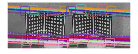


% this function allows me to visualize the epipolar line give the two
% images with the two pair of point
visualizeEpipolarLines( imgM1, imgM2, F_N, P1M_1, P2M_2);

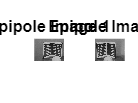


% looking for the epipole
%needs to applicate the decomposition svd to F matrix F = UWV' and select
%the last columns of U and V

[U W V] = svd (F_N);
last_col_U = U(1:2,end); % epipole left image
last_col_V = V(1:2,end); % epipole right image
figure;

Im = [imgM1 imgM2];
imshow(Im);
hold on
plot(last_col_U(1),last_col_U(2),'r*','Color', 'red','LineWidth', 8);
xv = [1:size(imgM1,2)];
plot(xv + last_col_V(1),last_col_V(2),'s', 'Color', [1,0,0], 'LineWidth', 8);
hold off
title ("Epipole image");


Part 2

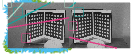

% imgRubik1 = imread('Rubik/Rubik1.pgm');
% imgRubik2 = imread('Rubik/Rubik2.pgm');

%list_ncc = findMatches(imgRubik1, imgRubik2, 'NCC');
%list_sift = findMatches(imgRubik1, imgRubik2, 'SIFT');

%figure, show_matches(imgRubik1, imgRubik2, list_ncc, 0, 10);
%figure, show_matches(imgRubik1, imgRubik2, list_sift, 1, 11);

list_sift = findMatches(imgM1, imgM2, 'SIFT');


%figure, show_matches(imgRubik1, imgRubik2, list_ncc, 0, 10);
figure, show_matches(imgM1, imgM2, list_sift, 1, 11), title("show matches");

% Find the correspondence point extimated with image matching
A_1 = [list_sift(:, 1:2)];
B_1 = [list_sift(:, 3:4)];

row_number = size(A_1, 1);
ones_column = ones(row_number, 1);

% convert in homogeneous coordinate and transpose, need to have every point in each column 
A = [A_1, ones_column];
A = A';
% want to consider a row vector
B = [B_1, ones_column];
B = B';

[bestF, consensus, outliers] = ransacF(A, B, 0.008);
% Points of first image 
A_2 = consensus(1:2, :)';
B_2 = consensus(4:5, :)';
visualizeEpipolarLines(imgM1, imgM2, bestF, A_2, B_2);

% [bestF, consensus, outliers] = ransacF(A, B, 0.01);
% visualizeEpipolarLines(imgM1, imgM2, bestF, A_1, B_1);







